% Define the data for lower limit, upper limit, and frequency
lowerLimits = [0,5,10,15,20,25,30,35,40]; 
upperLimits = [5,10,15,20,25,30,35,40,45]; 
frequencies = [12,34,52,54,23,13,14,5,4];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

         0             5           12    
         5            10           34    
        10            15           52    
        15            20           54    
        20            25           23    
        25            30           13    
        30            35           14    
        35            40            5    
        40            45            4    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 16.91


fprintf('Median: %.2f\n', medianValue);

Median: 17.50


fprintf('Mode: %.2f\n', modeValue);

Mode: 17.50


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 8.96


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 18.68


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: -1.18


fprintf('Karl: %.2f\n', Karl);

Karl: -0.07


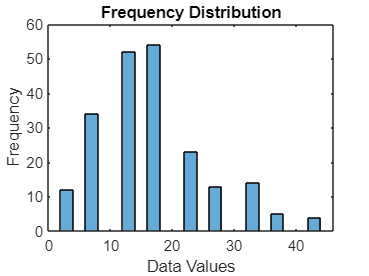


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');